# Optimization of Batch Reactor Temperature Profile

 Consider a batch reactor system with the following reaction scheme:


$$\begin{array}{l}
A+B\;\overset{k_1 }{\to} \;C\;\left(\mathrm{Main}\;\mathrm{Product}\right)\\
2B\;\overset{k_2 }{\to} \;D\;\;\left(\mathrm{Byproduct},2^{\mathrm{nd}} \;\mathrm{order}\;\mathrm{reaction}\right)
\end{array}$$


the process duration is 5400 s, and the kinetcs is written as:


$$    \frac{dC_A}{dt} = -k_1C_AC_B \\
    \frac{dC_B}{dt} = -k_1C_AC_B - 2k_2C_B^2 \\
    \frac{dC_C}{dt} = k_1C_AC_B \\
    \frac{dC_D}{dt} = k_2C_B^2$$


**Objective:** Maximize the final concentration of product C by optimizing the temperature profile T(t) over the course of the reaction. 

### Optimization Problem:


$$    \max_{T(t)} \quad  C_C(t_{end}) \\
    \text{subject to:} \quad  \text{Kinetic model equations} \\
    350 \text{ K} \leq T(t) \leq 393 \text{ K} \\
    0 \leq t \leq 5400 \text{ s}$$


Using the given data, develop a MATLAB script to solve this optimization problem and analyze the results.

clearvars, clc, clf, close
global k1_0 k2_0 E1 E2 R


#### Initial Data:

k1_0 = 7.55e8;
k2_0 = 5.75e11;
E1 = 7.90e4;
E2 = 9.80e4;
R = 8.314; % Gas constant

% Initial conditions and time span
C_A0 = 1;
C_B0 = 1;
C_C0 = 0;
C_D0 = 0;
tspan = [0 5400];


#### Optimization settings

n_segments = 10; % Number of temperature segments
T_min = 350; % Minimum temperature
T_max = 393; % Maximum temperature

% Initial guess: linear temperature profile
T_init = linspace(T_min, T_max, n_segments);

% Set optimization options
options = optimoptions('fmincon', 'MaxIterations', 100);

% Run optimization
[T_opt, fval] = fmincon(@(T) objective_function(T, tspan, [C_A0; C_B0; C_C0; C_D0]), ...
    T_init, [], [], [], [], T_min*ones(1,n_segments), T_max*ones(1,n_segments), [], options);


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


% Simulate system with optimal temperature profile
T_func_opt = @(t) interp1(linspace(0, tspan(2), n_segments), T_opt, t, 'pchip');
[t, C] = ode45(@(t, C) reaction_system(t, C, T_func_opt), tspan, [C_A0; C_B0; C_C0; C_D0]);

#### Plot results

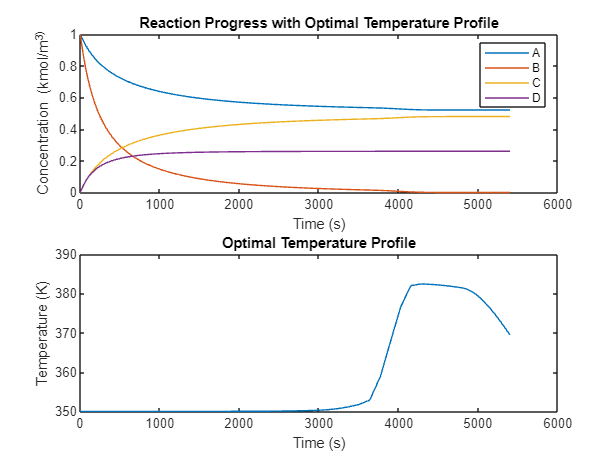

figure(1);
subplot(2,1,1);
plot(t, C);
xlabel('Time (s)');
ylabel('Concentration (kmol/m^3)');
legend('A', 'B', 'C', 'D');
title('Reaction Progress with Optimal Temperature Profile');

subplot(2,1,2);
plot(t, T_func_opt(t));
xlabel('Time (s)');
ylabel('Temperature (K)');
title('Optimal Temperature Profile');

fprintf('Optimal final concentration of C: %.4f kmol/m^3\n', -fval);

Optimal final concentration of C: 0.4795 kmol/m^3


#### Objective function

function J = objective_function(T, tspan, C0)
    T_func = @(t) interp1(linspace(0, tspan(2), length(T)), T, t, 'pchip');
    [~, C] = ode45(@(t, C) reaction_system(t, C, T_func), tspan, C0);
    J = -C(end, 3); % Negative because we want to maximize C
end

% ODE function
function dCdt = reaction_system(t, C, T_func)
    global k1_0 k2_0 E1 E2 R
    C_A = C(1); C_B = C(2); C_C = C(3); C_D = C(4);
    T = T_func(t);
    
    k1 = k1_0 * exp(-E1 / (R * T));
    k2 = k2_0 * exp(-E2 / (R * T));
    
    dCAdt = -k1 * C_A * C_B;
    dCBdt = -k1 * C_A * C_B - 2 * k2 * C_B^2;
    dCCdt = k1 * C_A * C_B;
    dCDdt = k2 * C_B^2;
    
    dCdt = [dCAdt; dCBdt; dCCdt; dCDdt];
end